# Tutorial 8: Workspace Analysis (Part 1)

This tutorial will show how workspace analysis can be run in CASPR for cable-driven robots. This tutorial will use the ideas from the following previous tutorials:

- `T1_load_robot.mlx`

Part 1 of this tutorial will focus on using the `PointWorkspaceSimulator` to compute and plot the workspace for different workspace conditions for a 2 DoF cable-driven robot.

clear;

## Setup

### Load the robot 

Load the 2 DoF robot in the manner shown in `T1_load_robot.mlx`.

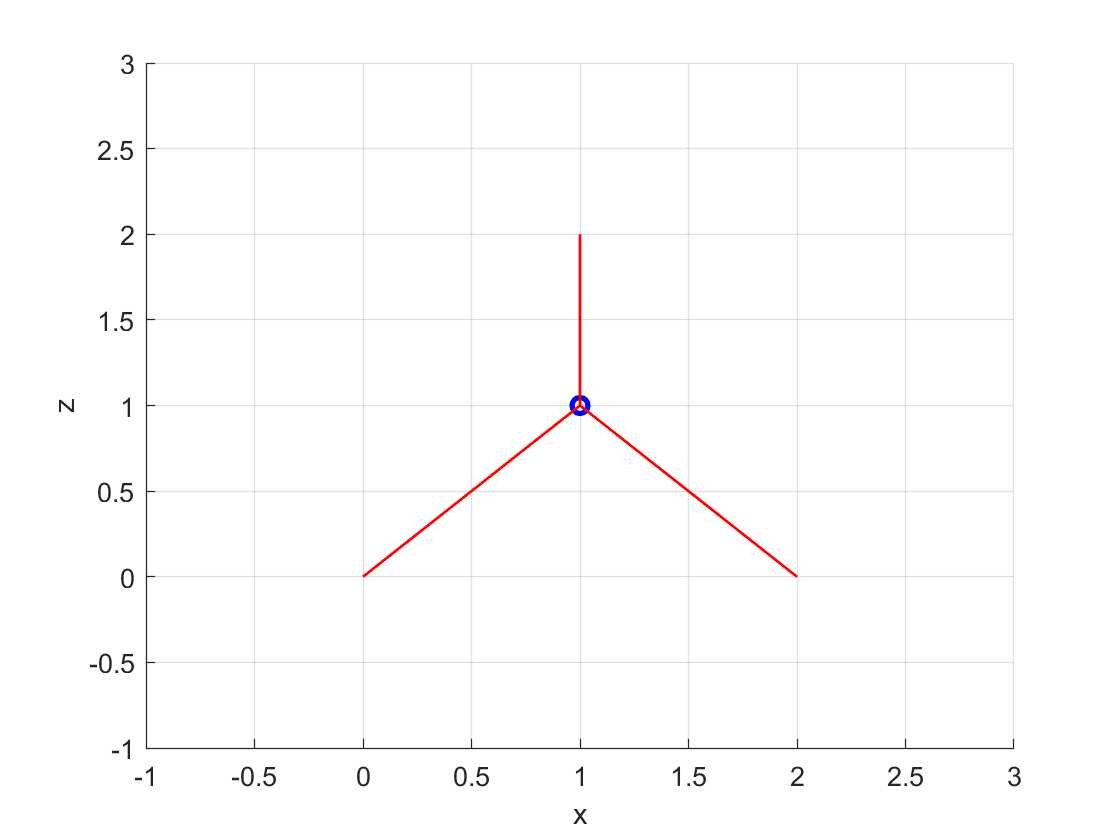

model_config = ModelConfig('Example point mass XZ');
cdpr_model = model_config.getModel('3_cables');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Setup the point-wise grid

A uniform (equal spacing) grid will be setup representing the set of points which the workspace analysis will be run.

% Set up the workspace simulator
% First the grid
q_min           = [0.05; -2.0];
q_max           = [1.95; 1.95];
q_step          = 0.05*ones(cdpr_model.numDofs, 1); 
uniform_grid    = UniformGrid(q_min, q_max, q_step, 'step_size');

### Setup plotting

dofs_to_plot = [1 2]; % Plot X axis as first DoF and Y axis as second DoF

For point-wise workspace, the following workspace conditions can be computed:

- Static Workspace: `WorkspaceStaticCondition`

- Wrench-Closure Workspace:` WrenchClosureCondition`

- Wrench-Feasible Workspace:` WrenchFeasibleCondition`

- Dynamic-Feasible Workspace:` DynamicFeasibleCondition`

- Cable Interference-Free Workspace:` InterferenceFreeCondition`

## 1) Static workspace analysis

The `PointWorkspaceSimulator` allows the point-wise workspace to be run. In this example, the static workspace will be first computed:

ws_condition_static = WorkspaceStaticCondition();

Create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_static = PointWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_static}, [], []);

Run the simulator over the specified grid:

ws_sim_static.run();

[INFO] Workspace point 1. Completion Percentage: 0.03
[INFO] Workspace point 2. Completion Percentage: 0.06
[INFO] Workspace point 3. Completion Percentage: 0.10
[INFO] Workspace point 4. Completion Percentage: 0.13
[INFO] Workspace point 5. Completion Percentage: 0.16
[INFO] Workspace point 6. Completion Percentage: 0.19
[INFO] Workspace point 7. Completion Percentage: 0.22
[INFO] Workspace point 8. Completion Percentage: 0.26
[INFO] Workspace point 9. Completion Percentage: 0.29
[INFO] Workspace point 10. Completion Percentage: 0.32
[INFO] Workspace point 11. Completion Percentage: 0.35
[INFO] Workspace point 12. Completion Percentage: 0.38
[INFO] Workspace point 13. Completion Percentage: 0.42
[INFO] Workspace point 14. Completion Percentage: 0.45
[INFO] Workspace point 15. Completion Percentage: 0.48
[INFO] Workspace point 16. Completion Percentage: 0.51
[INFO] Workspace point 17. Completion Percentage: 0.54
[INFO] Workspace point 18. Completion Percentage: 0.58
[INFO] Workspace po

Finally, plot the resulting 2-D workspace:

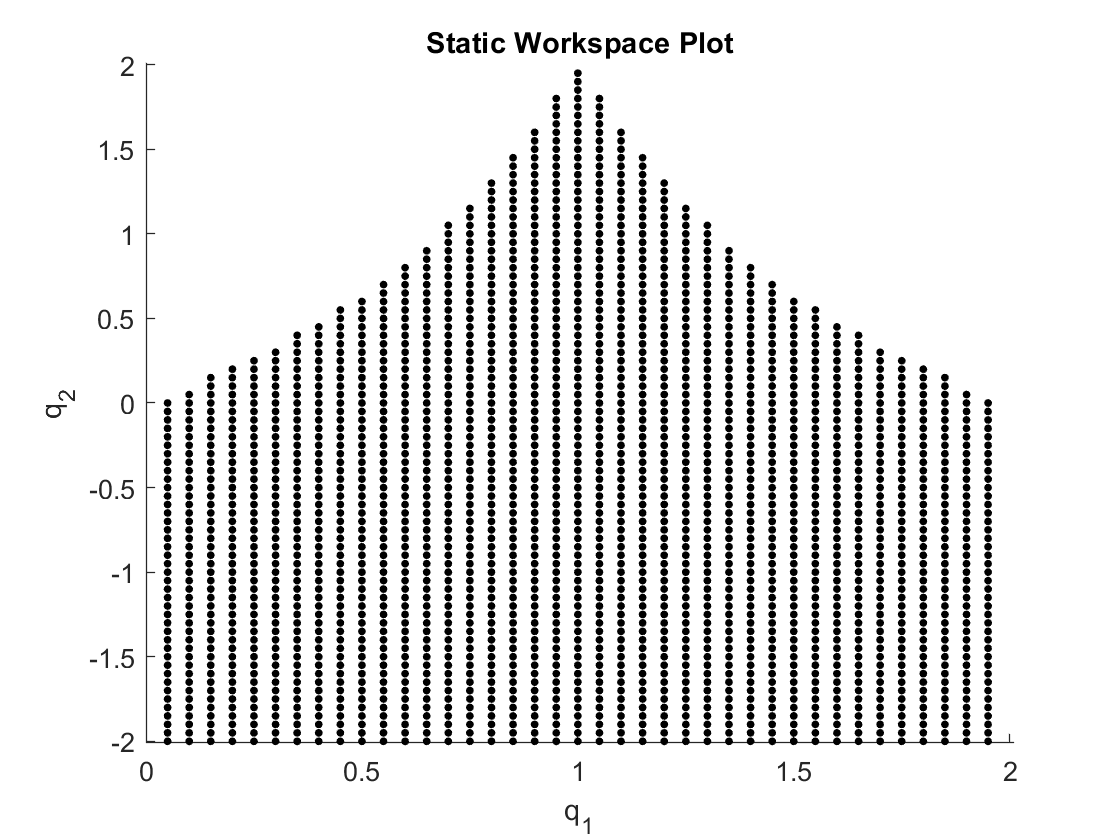

ws_sim_static.workspace.plotWorkspace(dofs_to_plot);
title('Static Workspace Plot');

## 2) Wrench-closure workspace analysis

Next, the wrench-closure workspace will be generated. 

ws_condition_wcc = WrenchClosureCondition();

Create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_wcw = PointWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_wcc}, [], []);

Run the simulator over the specified grid:

ws_sim_wcw.run();

[INFO] Workspace point 1. Completion Percentage: 0.03
[INFO] Problem infeasible
[INFO] Workspace point 2. Completion Percentage: 0.06
[INFO] Problem infeasible
[INFO] Workspace point 3. Completion Percentage: 0.10
[INFO] Problem infeasible
[INFO] Workspace point 4. Completion Percentage: 0.13
[INFO] Problem infeasible
[INFO] Workspace point 5. Completion Percentage: 0.16
[INFO] Problem infeasible
[INFO] Workspace point 6. Completion Percentage: 0.19
[INFO] Problem infeasible
[INFO] Workspace point 7. Completion Percentage: 0.22
[INFO] Problem infeasible
[INFO] Workspace point 8. Completion Percentage: 0.26
[INFO] Problem infeasible
[INFO] Workspace point 9. Completion Percentage: 0.29
[INFO] Problem infeasible
[INFO] Workspace point 10. Completion Percentage: 0.32
[INFO] Problem infeasible
[INFO] Workspace point 11. Completion Percentage: 0.35
[INFO] Problem infeasible
[INFO] Workspace point 12. Completion Percentage: 0.38
[INFO] Problem infeasible
[INFO] Workspace point 13. Completion

Finally, plot the resulting 2-D workspace:

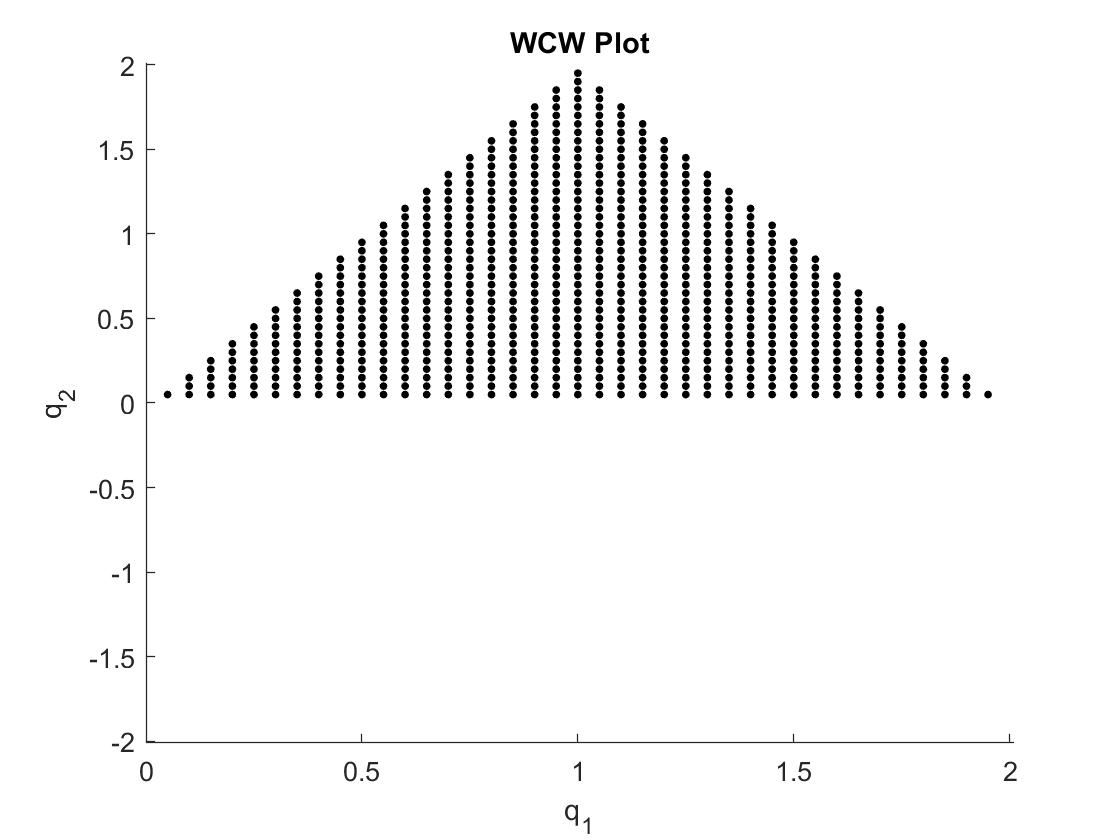

ws_sim_wcw.workspace.plotWorkspace(dofs_to_plot);
title('WCW Plot');

## 3) Wrench-feasible workspace analysis

Next, the wrench-feasible workspace will be generated. 

For the wrench-feasible workspace, a desired wrench set must be specified. In this example, the specified desired wrench set is the sum of the gravity force combined with a box of 20N in each dimension.

desired_wrench_set_vertices = [0; cdpr_model.bodyModel.bodies{1}.m*9.81] + 20*[-1 -1  1  1; ...
                                                                               -1  1 -1  1];                                                                          

The `ConvexPolytope` object stores the desired wrench set, and allows it to be drawn. 

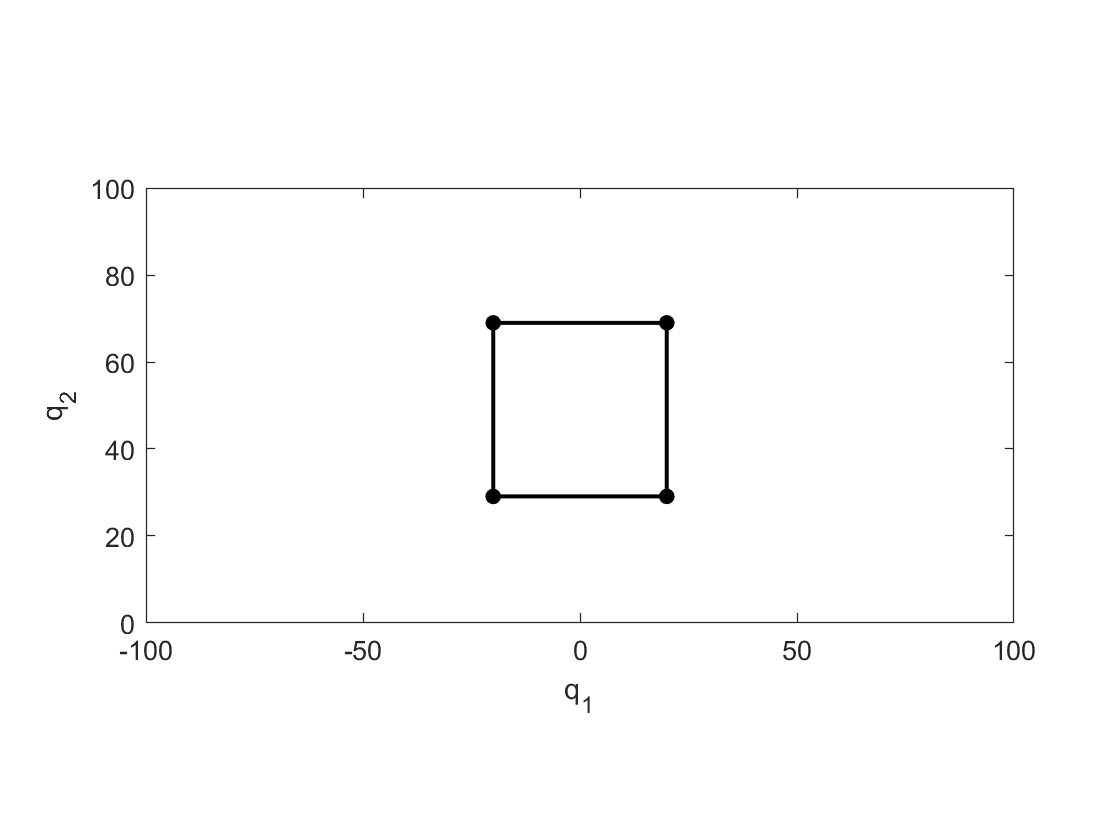

desired_wrench_set = ConvexPolytope(desired_wrench_set_vertices);
desired_wrench_set.plotConvexPolytope();
axis([-100 100 0 100]);

Setup the workspace condition:

ws_condition_wfc = WrenchFeasibleCondition(desired_wrench_set);

Create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_wfw = PointWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_wfc}, [], []);

Run the simulator over the specified grid:

ws_sim_wfw.run();

[INFO] Workspace point 1. Completion Percentage: 0.03
[INFO] Workspace point 2. Completion Percentage: 0.06
[INFO] Workspace point 3. Completion Percentage: 0.10
[INFO] Workspace point 4. Completion Percentage: 0.13
[INFO] Workspace point 5. Completion Percentage: 0.16
[INFO] Workspace point 6. Completion Percentage: 0.19
[INFO] Workspace point 7. Completion Percentage: 0.22
[INFO] Workspace point 8. Completion Percentage: 0.26
[INFO] Workspace point 9. Completion Percentage: 0.29
[INFO] Workspace point 10. Completion Percentage: 0.32
[INFO] Workspace point 11. Completion Percentage: 0.35
[INFO] Workspace point 12. Completion Percentage: 0.38
[INFO] Workspace point 13. Completion Percentage: 0.42
[INFO] Workspace point 14. Completion Percentage: 0.45
[INFO] Workspace point 15. Completion Percentage: 0.48
[INFO] Workspace point 16. Completion Percentage: 0.51
[INFO] Workspace point 17. Completion Percentage: 0.54
[INFO] Workspace point 18. Completion Percentage: 0.58
[INFO] Workspace po

Finally, plot the resulting 2-D workspace:

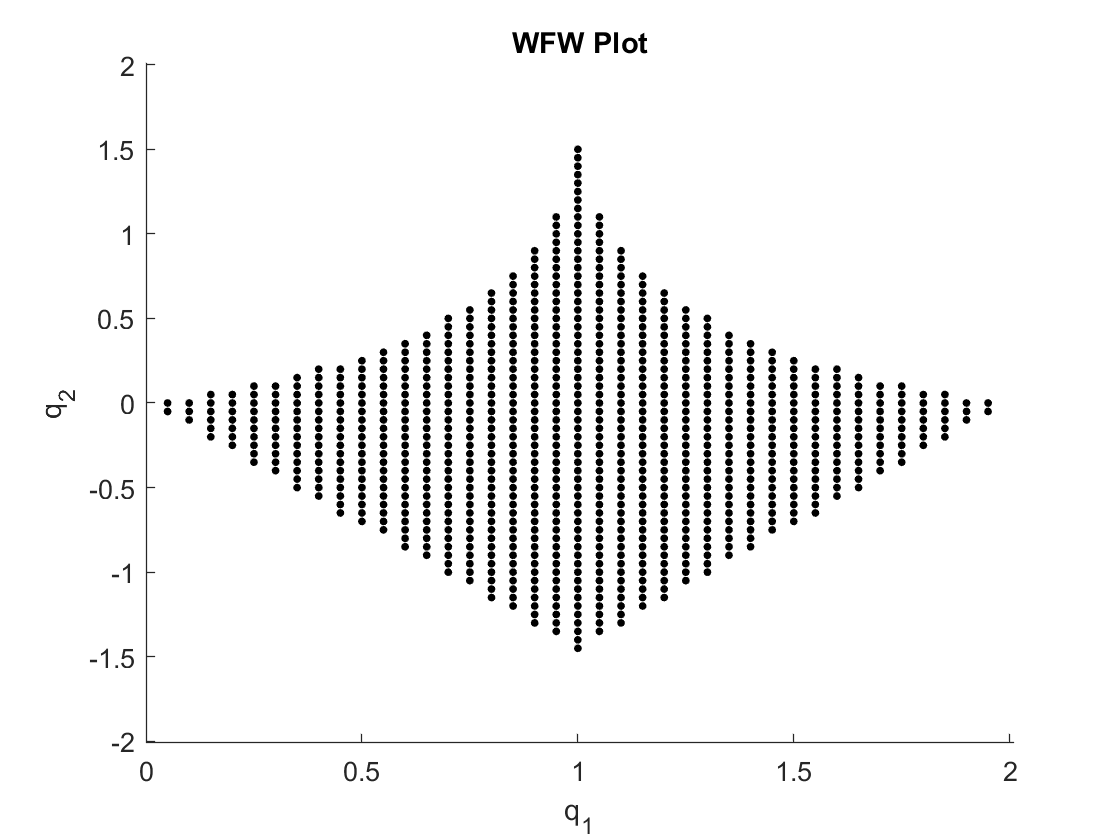

ws_sim_wfw.workspace.plotWorkspace(dofs_to_plot);
title('WFW Plot');

## Multiple workspace conditions

In addition to single conditions in the above examples, it is possible to generate the workspace for multiple workspace conditions simultaneously, by simply providing multiple conditions:

ws_conditions = {ws_condition_static, ws_condition_wcc, ws_condition_wfc};
ws_sim_multiple = PointWorkspaceSimulator(cdpr_model, uniform_grid, ws_conditions, [], []);
ws_sim_multiple.run();

[INFO] Workspace point 1. Completion Percentage: 0.03
[INFO] Problem infeasible
[INFO] Workspace point 2. Completion Percentage: 0.06
[INFO] Problem infeasible
[INFO] Workspace point 3. Completion Percentage: 0.10
[INFO] Problem infeasible
[INFO] Workspace point 4. Completion Percentage: 0.13
[INFO] Problem infeasible
[INFO] Workspace point 5. Completion Percentage: 0.16
[INFO] Problem infeasible
[INFO] Workspace point 6. Completion Percentage: 0.19
[INFO] Problem infeasible
[INFO] Workspace point 7. Completion Percentage: 0.22
[INFO] Problem infeasible
[INFO] Workspace point 8. Completion Percentage: 0.26
[INFO] Problem infeasible
[INFO] Workspace point 9. Completion Percentage: 0.29
[INFO] Problem infeasible
[INFO] Workspace point 10. Completion Percentage: 0.32
[INFO] Problem infeasible
[INFO] Workspace point 11. Completion Percentage: 0.35
[INFO] Problem infeasible
[INFO] Workspace point 12. Completion Percentage: 0.38
[INFO] Problem infeasible
[INFO] Workspace point 13. Completion

After running the analysis for all of the conditions, you can choose to plot the intersection of all conditions:

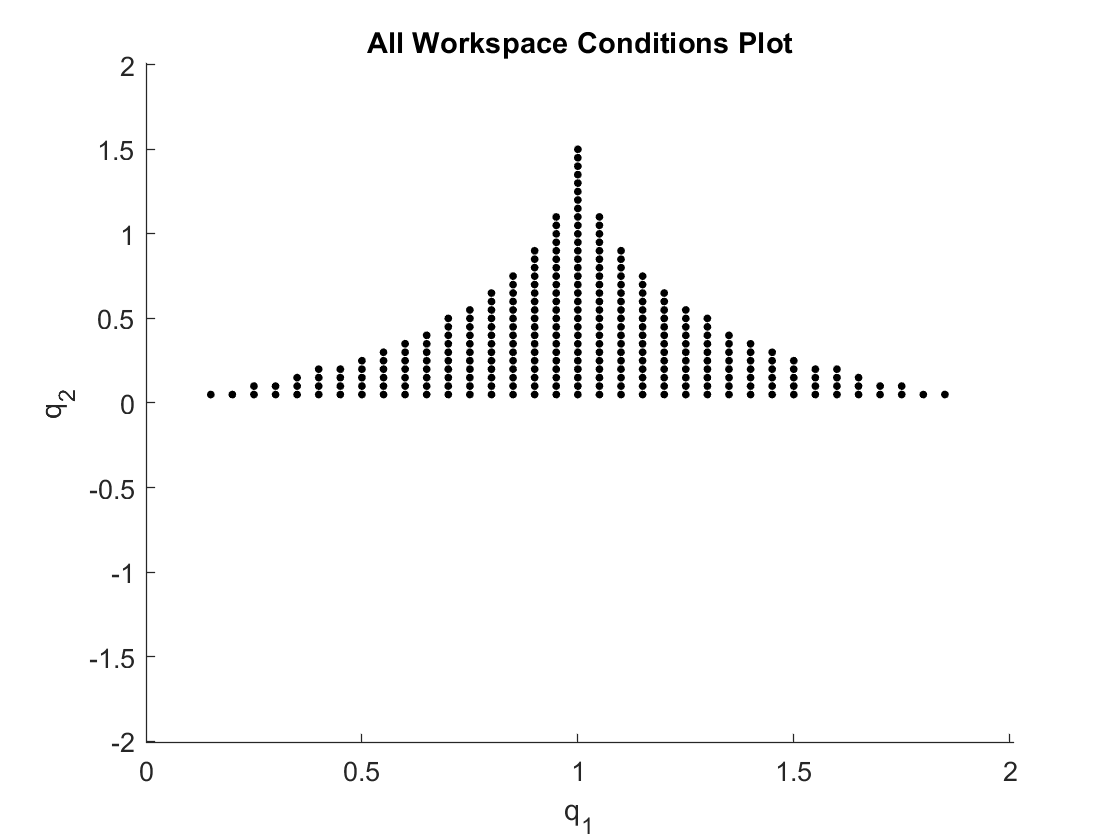

ws_sim_multiple.workspace.plotWorkspace(dofs_to_plot);
title('All Workspace Conditions Plot');

Or plot one or more of the conditions, for example just the `ws_condition_wcc `(index number 2 from `ws_conditions`):

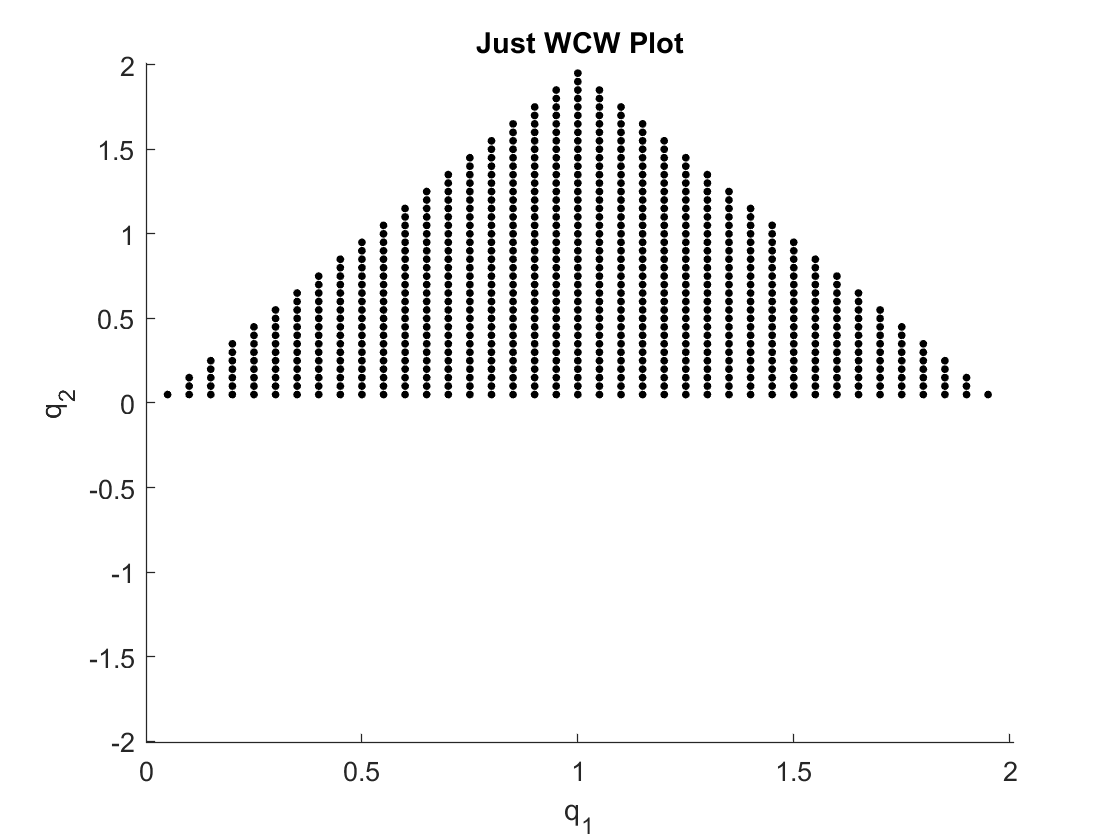

ws_sim_multiple.workspace.plotWorkspace(dofs_to_plot, [2]);
title('Just WCW Plot');

Or the intersection of `ws_condition_static `and` ws_condition_wcc` (indices number 1 and 2 from `ws_conditions`):

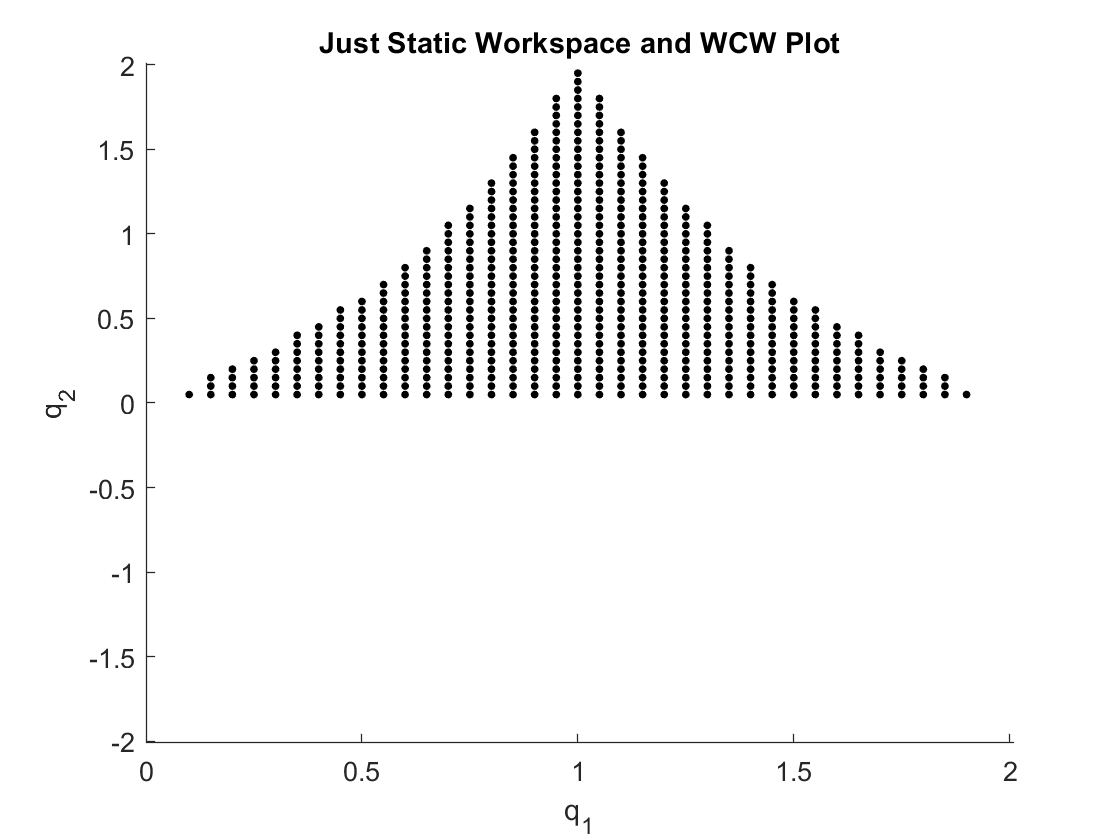

ws_sim_multiple.workspace.plotWorkspace(dofs_to_plot, [1 2]);
title('Just Static Workspace and WCW Plot');